**Developing and Evaluating an Anomaly Detection System**

% % Always positive variables => log-differences (log-returns)
Indices_Currencies = [XAUBGNL BDIY CRY Cl1 DXY EMUSTRUU GBP JPY LF94TRUU LF98TRUU LG30TRUU LMBITR LP01TREU...
       LUACTRUU LUMSTRUU MXBR MXCN MXEU MXIN MXJP MXRU MXUS VIX];

% Possibly negative variables => first differences
InterestRates = [EONIA GTDEM10Y GTDEM2Y GTDEM30Y GTGBP20Y GTGBP2Y GTGBP30Y...
    GTITL10YR GTITL2YR GTITL30YR GTJPY10YR GTJPY2YR GTJPY30YR US0001M USGG3M USGG2YR GT10 USGG30YR];

Data = [diff(log(Indices_Currencies)) ECSURPUS(2:end) diff(InterestRates) GTITL10YR(2:end) GTDEM10Y(2:end)]; % make stationary
Response = Y(2:end); % we lose one observation (the first)

### **Multivariate perspective**

Matrix of scatter plots comparing our Xs by using the our Y as grouping variable (I plot just a selection of features, and they are already too many).

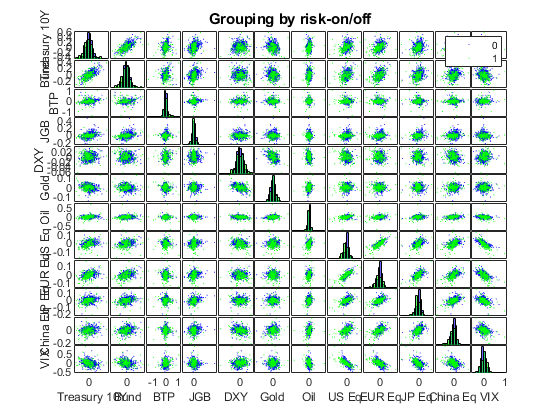

figure
Dat4Plot = [diff(GT10) diff(GTDEM10Y) diff(GTITL10YR) diff(GTJPY10YR)...
    diff(log(DXY)) diff(log(XAUBGNL)) diff(log(Cl1)) diff(log(MXUS))...
    diff(log(MXEU)) diff(log(MXJP)) diff(log(MXCN)) diff(log(VIX))];
xnames = {'Treasury 10Y', 'Bund', 'BTP', 'JGB', 'DXY', 'Gold', 'Oil', 'US Eq', 'EUR Eq', 'JP Eq', 'China Eq', 'VIX'};
gplotmatrix(Dat4Plot,[],Response, [],[],[],[],'grpbars', xnames)
title('Grouping by risk-on/off')

### Step1: creating training/cross-validation/test set

First we reshuffle.

Then we divide our data as follows:

- Training set = 80% of the examples, all of which are good (Y = 0)

- Cross-validation set = 10% of the examples such that Y = 0, and 50% of the anomalous examples, i.e. Y = 1;

- Test set = same as above.

nObs = length(Response); % #data
nObsNorm = sum(Response == 0); % #normal data points
nObsAbNorm = nObs - nObsNorm; % #abnormal data points
nObsTrain = round(0.80*nObsNorm); % #length training set
nObsCVNorm = round(0.10*nObsNorm); % #length normal portion of CV set
nObsCVabNorm = round(nObsAbNorm/2); % #length abnormal portion of CV set
nObsTest_abNorm = nObsAbNorm - nObsCVabNorm; % #length abnormal portion of Train set

% Reshuffling the sample
idxPermutation = randperm(nObs);
X = Data(idxPermutation,:);
Response = Response(idxPermutation);

% dividing normal/abnormal
Xnormal = X(Response == 0,:);
Xabnormal = X(Response == 1,:);
Yabnormal = Response(Response == 1,:);

XTrain = Xnormal(1:nObsTrain,:);
XCV = [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,:); Xabnormal(1:nObsCVabNorm,:)];
XTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,:); Xabnormal(nObsCVabNorm+1:end,:)];

yCV = zeros(length(XCV),1);
yCV(end-nObsCVabNorm+1:end) = Yabnormal(1:nObsCVabNorm);
yTest = zeros(length(XTest),1);
yTest(end-nObsTest_abNorm+1:end) = Yabnormal(nObsCVabNorm+1:end);

#### Step 2: training the model

Let's model p(X) from the training set data:

- We still assume a multivariate Gaussian distribution for our data (even if we know that it's not true);

- We train the model, i.e., we estimate the parameters, the vector of means and the covariance matrix.

sigma = cov(XTrain);
sigma = 0.5*(sigma+sigma'); % ensures symmetry
mu = mean(XTrain);

#### Step 3: fine tuning the hyperparameter, the threshold ϵ

On the cross-validation set:

- We compute the probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ

- If p(X) < ϵ (anomaly), then Y = 1;

- If p(X) ≥ ϵ (normal), then Y = 0;

- We select the value of ϵ that obtains the best score in terms of `[select the most appropriate metric according to the specific problem: F1 score, Precision, Recall, True positive, False positive, False negative, True negative]`.

- Usually the different values of are in the range [min(p(X), max(p(X)].

p = mvnpdf(XCV,mu,sigma); % compute the probability density function for each example

[bestEpsilon, bestF1] = OptimThreshold(yCV, p) % find the optimal epsilon

bestEpsilon = 2.3303e+45

bestF1 = 0.7651

#### Step 4: testing the model

On the test set:

- We compute the probability density function p(X) for each example in X;

- Using the optimal hyperparameters ϵ, we check if  p(X) < ϵ;

- If p(X) < ϵ (anomaly), then we predict Y = 1;

- If p(X) ≥ ϵ (normal), then we predict Y = 0;

- We compare our predictions with the ground truth (and we calculate usual performance metrics).

p = mvnpdf(XTest,mu,sigma);
predictions = p < bestEpsilon;
tp = sum((predictions == 1) & (yTest == 1))

tp = 116

fp = sum((predictions == 1) & (yTest == 0))

fp = 66

fn = sum((predictions == 0) & (yTest == 1))

fn = 2

prec = tp / (tp + fp)

prec = 0.6374

rec = tp / (tp + fn)

rec = 0.9831

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7733

**GLOBAL EQUITY INDEX**

- use a discriminating variable, which separates abnormally positive situations from abnormally negative ones, for example an aggregate equity index (in bad situations equities tend to go down, overall) - kind of sanity check.

We will give a try to the latter approach; thus:

- we define a equally weighted global equity index, using a simple average of the equity assets in the dataset;

- we need it anly for cross-validation set and test set;

On the cross-validation set we use a slightly different procedure than before:

- We compute the probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ;

- If p(X) < ϵ (ie suspected anomaly), and the global equity index return is worse than **a given threshold T** (ie the equity market goes down), then Y = 1;

- Otherwise Y = 0;

- We define the threshold T as a percentile, based on a given probability pPercentile, that is:

                                                                        T = percentile(global equity index return, pPercentile);

- So we have another hyperparameter to be optimized, pPercentile;

- Basically we do a grid search on epsilon and pPercentile (ie a double loop);

- We select the value of ϵ that obtains the best score in terms of `[select the most appropriate metric according to the specific problem: F1 score, Precision, Recall, True positive, False positive, False negative, True negative]`.

Compute the "global equity index" equally weighting the 7 equity assets in our dataset (column 16:22 of the features' matrix).

% equity indices are column 16-22 (see above)
globalEquityCV = mean(XCV(:,16:22),2); % global equity index for the CV set
globalEquityTest = mean(XTest(:,16:22),2); % global equity index for the test set

Compute the probability density function for each example in the cross-validation set.

p = mvnpdf(XCV,mu,sigma);

Do the grid search over the parameter space of epsilon and pPercentile.

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_pPercentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;

%loop for pQuantile
for pPercentile = 1:1:99

    equityThreshold = prctile(globalEquityCV,pPercentile);

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (globalEquityCV<equityThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_pPercentile = pPercentile;
        end
    end
end

bestF1

bestF1 = 0.7568

bestPrecision

bestPrecision = 0.6328

bestRecall

bestRecall = 0.9412

bestEpsilon

bestEpsilon = 2.3303e+45

best_pPercentile

best_pPercentile = 99

Now, on the test set:

- We compute the probability density function p(X) for each example in X;

- Using the optimal hyperparameters ϵ, and bestpQuantile, we check if  p(X) < ϵ AND the global equity index return is worse than the threshold T = percentile(global equity index return, pQuantile);

- In that case our prediction is Y = 1;

- Otherwise the prediction is Y = 0;

- We compare our predictions with the ground truth (and we calculate usual performance metrics).

p = mvnpdf(XTest,mu,sigma);
equityThreshold = prctile(globalEquityTest,best_pPercentile);
predictions = (p < bestEpsilon) & (globalEquityTest<equityThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 115

fp = sum((predictions == 1) & (yTest == 0))

fp = 65

fn = sum((predictions == 0) & (yTest == 1))

fn = 3

prec = tp / (tp + fp)

prec = 0.6389

rec = tp / (tp + fn)

rec = 0.9746

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7718

The results on the test sample are roughly in line with the previous model: probably the idea of discriminating only on the basis of equity returns, even if it corresponds to financial intuition, does not capture the whole reality of the phenomenon, and it must be refined.

**GLOBAL EQUITY INDEX AND VIX (option implied volatility)**

% equity indices are column 16-22 (see above)
globalEquityCV = mean(XCV(:,16:22),2); % global equity index for the CV set
globalEquityTest = mean(XTest(:,16:22),2); % global equity index for the test set
VixCV = XCV(:,23);
Vixtest = XTest(:,23);

Compute the probability density function for each example in the cross-validation set.

p = mvnpdf(XCV,mu,sigma);

Do the grid search over the parameter space of epsilon and pPercentile.

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_pPercentile = 0;
best_p1Percentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;
besttp = 0;
bestfp = 0;
bestfn = 0;

%loop for pQuantile
for pPercentile = 1:1:99
for p1Percentile = 1:1:99
    
    equityThreshold = prctile(globalEquityCV,pPercentile);
    VixThreshold = prctile(VixCV,p1Percentile);

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (globalEquityCV<equityThreshold) & (VixCV<VixThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_pPercentile = pPercentile;
            best_p1Percentile = p1Percentile;
            besttp = tp;
            bestfp = fp;
            bestfn = fn;
        end
    end
end
end

bestF1

bestF1 = 0.7619

bestPrecision

bestPrecision = 0.6400

bestRecall

bestRecall = 0.9412

bestEpsilon

bestEpsilon = 2.3303e+45

best_pPercentile

best_pPercentile = 99

best_p1Percentile

best_p1Percentile = 99

besttp

besttp = 112

bestfp 

bestfp = 63

bestfn

bestfn = 7

p = mvnpdf(XTest,mu,sigma);
equityThreshold = prctile(globalEquityTest,best_pPercentile);
VixThreshold = prctile(Vixtest,best_p1Percentile);
predictions = (p < bestEpsilon) & (globalEquityTest<equityThreshold) & (Vixtest<VixThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 113

fp = sum((predictions == 1) & (yTest == 0))

fp = 65

fn = sum((predictions == 0) & (yTest == 1))

fn = 5

prec = tp / (tp + fp)

prec = 0.6348

rec = tp / (tp + fn)

rec = 0.9576

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7635

### Only Vix

p = mvnpdf(XCV,mu,sigma);
VixCV = XCV(:,23);
Vixtest = XTest(:,23);

maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_p1Percentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;
besttp = 0;
bestfp = 0;
bestfn = 0;
VixThreshold=0;

%loop for pQuantile
for p1Percentile = 1:1:99
    
    VixThreshold = prctile(VixCV,p1Percentile);

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (VixCV<VixThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_p1Percentile = p1Percentile;
            besttp = tp;
            bestfp = fp;
            bestfn = fn;
        end
    end
end

bestF1

bestF1 = 0.7703

bestPrecision

bestPrecision = 0.6441

bestRecall

bestRecall = 0.9580

bestEpsilon

bestEpsilon = 2.3303e+45

best_p1Percentile

best_p1Percentile = 99

besttp

besttp = 114

bestfp 

bestfp = 63

bestfn

bestfn = 5

p = mvnpdf(XTest,mu,sigma);
VixThreshold = prctile(Vixtest,best_p1Percentile);
predictions = (p < bestEpsilon) & (Vixtest<VixThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 114

fp = sum((predictions == 1) & (yTest == 0))

fp = 66

fn = sum((predictions == 0) & (yTest == 1))

fn = 4

prec = tp / (tp + fp)

prec = 0.6333

rec = tp / (tp + fn)

rec = 0.9661

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7651

### **BTP-BUND spread and equity index mean**

p = mvnpdf(XCV,mu,sigma);
spreadCV = (XCV(:,end-1)-XCV(:,end))*100;
spreadtest = (XTest(:,end-1)-XTest(:,end))*100;

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_pPercentile = 0;
best_p1Percentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;
besttp = 0;
bestfp = 0;
bestfn = 0;

%loop for pQuantile
for pPercentile = 1:1:99
for p1Percentile = 1:1:99
    
    equityThreshold = prctile(globalEquityCV,pPercentile);
    spreadThreshold = prctile(spreadCV,p1Percentile);

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (globalEquityCV<equityThreshold) & (spreadCV<spreadThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_pPercentile = pPercentile;
            best_p1Percentile = p1Percentile;
            besttp = tp;
            bestfp = fp;
            bestfn = fn;
        end
    end
end
end

bestF1

bestF1 = 0.7483

bestPrecision

bestPrecision = 0.6286

bestRecall

bestRecall = 0.9244

bestEpsilon

bestEpsilon = 2.3303e+45

best_pPercentile

best_pPercentile = 99

best_p1Percentile

best_p1Percentile = 99

besttp

besttp = 110

bestfp 

bestfp = 65

bestfn

bestfn = 9

p = mvnpdf(XTest,mu,sigma);
equityThreshold = prctile(globalEquityTest,best_pPercentile);
spreadThreshold = prctile(spreadtest,best_p1Percentile);
predictions = (p < bestEpsilon) & (globalEquityTest<equityThreshold) & (spreadtest<spreadThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 113

fp = sum((predictions == 1) & (yTest == 0))

fp = 65

fn = sum((predictions == 0) & (yTest == 1))

fn = 5

prec = tp / (tp + fp)

prec = 0.6348

rec = tp / (tp + fn)

rec = 0.9576

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7635

## Only BTP-Bund spread

p = mvnpdf(XCV,mu,sigma);
spreadCV = (XCV(:,end-1)-XCV(:,end))*100;
spreadtest = (XTest(:,end-1)-XTest(:,end))*100;

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_pPercentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;
besttp = 0;
bestfp = 0;
bestfn = 0;

%loop for pQuantile
for pPercentile = 1:1:99
    
    spreadThreshold = prctile(spreadCV,pPercentile);
    

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (spreadCV<spreadThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_pPercentile = pPercentile;
            besttp = tp;
            bestfp = fp;
            bestfn = fn;
        end
    end
end

bestF1

bestF1 = 0.7568

bestPrecision

bestPrecision = 0.6328

bestRecall

bestRecall = 0.9412

bestEpsilon

bestEpsilon = 2.3303e+45

best_pPercentile

best_pPercentile = 99

besttp

besttp = 112

bestfp 

bestfp = 65

bestfn

bestfn = 7



p = mvnpdf(XTest,mu,sigma);
spreadThreshold = prctile(spreadtest,best_pPercentile);
predictions = (p < bestEpsilon) & (spreadtest<spreadThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 114

fp = sum((predictions == 1) & (yTest == 0))

fp = 66

fn = sum((predictions == 0) & (yTest == 1))

fn = 4

prec = tp / (tp + fp)

prec = 0.6333

rec = tp / (tp + fn)

rec = 0.9661

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7651